clc; clear; close all
cd 'G:\Jiaxu Flashdrive Backup\GPR model'
addpath 'G:\Jiaxu Flashdrive Backup\code\functions'

bre_top_imds = imageDatastore("G:\Jiaxu Flashdrive Backup\GPR model\gpr test images\brenner gpr test\test20\from top");
bre_bot_imds = imageDatastore("G:\Jiaxu Flashdrive Backup\GPR model\gpr test images\brenner gpr test\test20\from bot");
load('gpr_models.mat');

%%%%%%%%%%%%%%%%%%%%% top %%%%%%%%%%%%%%%%%%%%%
for i = 1:length(bre_top_imds.Files)
    bre_img_top(:,:,i) = readimage(bre_top_imds,i);
end

for i = 1:length(bre_top_imds.Files)
    bre_sharp_top(i) = brenner(bre_img_top(:,:,i));
end
norm_bre_sharp_top = norm_array(bre_sharp_top,'brenner');
norm_bre_sharp_top_combine = [norm_bre_sharp_top, flip(norm_bre_sharp_top(1:5))];

bre_top_height = linspace(0,5,6);
bre_top_height_combine = [bre_top_height,flip(bre_top_height(1:5))];

for i = 1:length(norm_bre_sharp_top_combine)
    bre_top_h_pred(i) = predict(gpr_bre_top,norm_bre_sharp_top_combine(i));
end
%%%%%%%%%%%%%%%%%%%%% bot %%%%%%%%%%%%%%%%%%%%%
for i = 1:length(bre_bot_imds.Files)
    bre_img_bot(:,:,i) = readimage(bre_bot_imds,i);
end

for i = 1:length(bre_bot_imds.Files)
    bre_sharp_bot(i) = brenner(bre_img_bot(:,:,i));
end
norm_bre_sharp_bot = norm_array([bre_sharp_top(1) bre_sharp_bot],'brenner');
norm_bre_sharp_bot_combine = [norm_bre_sharp_bot(2:end), flip(norm_bre_sharp_bot(1:5))];

bre_bot_height = linspace(-1,-5,5);
bre_bot_height_combine = [bre_bot_height,flip(bre_bot_height(1:4)),0];

for i = 1:length(norm_bre_sharp_bot_combine)
    bre_bot_h_pred(i) = predict(gpr_bre_bot,norm_bre_sharp_bot_combine(i));
end

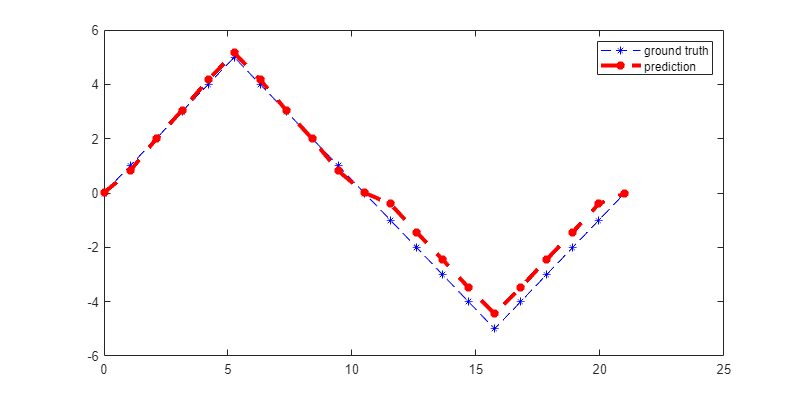

figure(1)
height_out = [bre_top_height_combine';bre_bot_height_combine'];
norm_sharp = [norm_bre_sharp_top_combine';norm_bre_sharp_bot_combine'];
prediction = [bre_top_h_pred';bre_bot_h_pred'];

x_axis = length(norm_bre_sharp_top_combine)+length(norm_bre_sharp_bot_combine);
plot(linspace(0,x_axis,x_axis),[bre_top_height_combine,bre_bot_height_combine],'b--*'); hold on;
plot(linspace(0,x_axis,x_axis),[bre_top_h_pred,bre_bot_h_pred],'r--*',LineWidth=3); hold on
legend('ground truth','prediction')
hold off
x0=0; y0=0;
width=800;
height=400;
set(gcf,'position',[x0,y0,width,height])

% bre_test_result = importdata('brenner_gpr_test_result_all.txt');
% 
% x_axis = length(bre_test_result);
% plot(linspace(0,x_axis,x_axis),bre_test_result(:,1),'b--*'); hold on;
% plot(linspace(0,x_axis,x_axis),bre_test_result(:,3),'r--*',LineWidth=3); hold on
% 
% xline(21,'--'); hold on
% xline(21*2,'--'); hold on
% xline(21*3,'--');
% hold off
% legend('ground truth','prediction')
% xlabel('Frame');
% ylabel('\mum from ground truth')
% x0=0; y0=0;
% width=800;
% height=200;
% set(gcf,'position',[x0,y0,width,height])